# Function 3:


$$f\left(z\right)=z^3 -2z+2$$


The complex roots of this function are:

-1.7693 + 0.0000i

 0.8846 + 0.5897i

 0.8846 - 0.5897 i

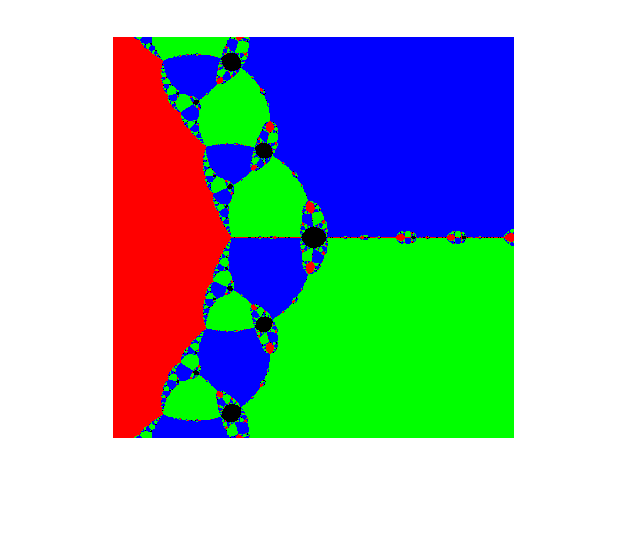

x=-2:.01:2;
x=x+eps;
y=x;
i=complex(0,1);
[X Y]=meshgrid(x,y);
Z=X+i*Y;
for j=1:64
    Z=Z-(Z.^3-2*Z+2)./(3*Z.^2-2);
end
%coefficients in order 1 0 -2 2
r=roots([1 0 -2 2]);
Z1=abs(Z-r(1))<=0.1;
Z2=abs(Z-r(2))<=0.1;
Z3=abs(Z-r(3))<=0.1;
a(:,:,1)=Z1*1;
a(:,:,2)=Z2*1;
a(:,:,3)=Z3*1;
figure
imshow(a)